## Toy example on how to visualize fastcore model output using the new pipeline

This example is meant to show the different types of visualizations you can do to further inspect your models build with fastcore. 

Read in object with the stored singleModelAnalysis:

workingPath = "/Users/leonie.thomas/Documents/fastcore_workflow_with_vanille";
% load(workingPath + filesep + "context_specific_models" + filesep + "20260326_0311/20260326_0311_project_sampling_2304_loopless.mat")
%load('/Users/leonie.thomas/Documents/fastcore_workflow_with_vanil le/context_specific_models/20260326_0311/20260326_0311_project_sampling_2104_loopless_KO_WT.mat')

% project.models.WT.analysis = rmfield(project.models.WT.analysis, ["FBA", "FVA", "sampling", "parameters"]);
% project.models.PLV.analysis = rmfield(project.models.PLV.analysis, ["FBA", "FVA", "sampling", "parameters"]);
% project.models.KO.analysis = rmfield(project.models.KO.analysis, ["FBA", "FVA", "sampling", "parameters"]);

load(workingPath + filesep + "context_specific_models" + filesep + "20260501_1218/20260501_1218_project_singleModelanalysi.mat")
sampleProj = project;

First difference here is that the new object was run with new sets of default Parameters, for example FBA minNorm was set from 'zero' to 'one'. This changes my results in terms of the lactate export. 

How do the imports change under 'one' minNorm ? 


% choose which models to compare
modelList = ["A1", "A2",  "A3", "C1", "C2", "C3"];
% choose which of the analysis stored in the object to compare 
% by default: the most recent one (name of the object is the date)
% [sampleProj, analysisIDOneNorm] = chooseActiveAnalysisForComparison(sampleProj,modelList,0,1); %,["analysis_20260414_1828", "analysis_20260414_2032","analysis_20260414_1956"]);
% projOneNorm = sampleProj;
% 
% [projOneNorm,comparisonName] = modelsComparison(projOneNorm,modelList, analysisIDOneNorm,...
%                                                 referenceModel,["modelStructureComparison", "modelFunctionalComparison" ],...
%                                                 identifier);
% plotsOne = projOneNorm.comparisons.(comparisonName).plots;

% choose the model which entails all the reactions and metabolites
referenceModel = "consistent_medium_constrained_model";
% choose which of the analysis you want to expecute
identifier = "_test";

% the FBA perfomed is not good, performed with the "one" parameter -> perform another one with the "zero" parameter

% opts = detectImportOptions(workingPath + filesep +'scr/defaultParametersAnalysis.csv');
% opts.VariableTypes{3} = 'char'; % making sure that the last column with the values is read in as a character 
% % Ensure all rows are read (no early stopping)
% opts.DataLines = [1 Inf];
% parametersAnalysis = readtable(workingPath + filesep +'scr/defaultParametersAnalysis.csv', opts);
% 
% %% set the minNorm to zero
% parametersAnalysis.Value(parametersAnalysis.Parameter == "minNorm" & parametersAnalysis.Analysis == "FBA") = {'zero'};
% 
% modelList = ["PLV","WT", "KO"];
% analysisList = ["FBA"];
% 
% sampleProj = singleModelAnalysis(sampleProj,modelList,analysisList,parametersAnalysis);
[sampleProj, analysisID] = chooseActiveAnalysisForComparison(sampleProj,modelList,0,1);

### Run downstream comparative analysis: 

modelsToTest = 1×7 string array
    "A1"    "A2"    "A3"    "C1"    "C2"    "C3"    "consistent_medium_constrained_model"


Transcripts will temporarily be removed to allow matching with the discretized data.
1213 of 1247 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1230 of 1264 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1242 of 1276 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1234 of 1268 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1211 of 1245 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1209 of 1243 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1221 of 1255 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1237 of 1271 genes of the model matched


ans = 6×3 table
          count_reactions    count_metabolites    count_genes
          _______________    _________________    ___________

    A1       {[2481]}            {[1985]}          {[1247]}  
    A2       {[2442]}            {[1958]}          {[1264]}  
    A3       {[2473]}            {[1998]}          {[1276]}  
    C1       {[2458]}            {[1959]}          {[1255]}  
    C2       {[2441]}            {[1955]}          {[1271]}  
    C3       {[2427]}            {[1955]}          {[1243]}  


Only supports 2 to 4 sets. Therefore a simple intersection heatmap will be plotted here!


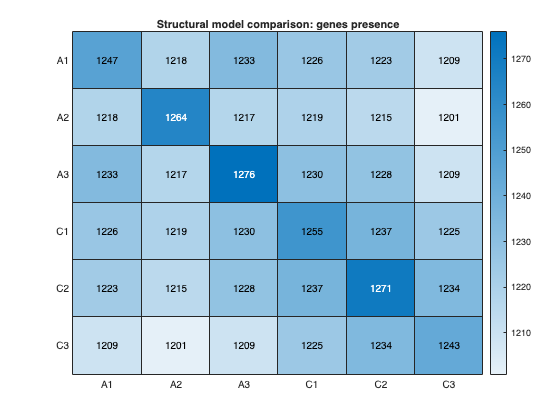

Only supports 2 to 4 sets. Therefore a simple intersection heatmap will be plotted here!
Only supports 2 to 4 sets. Therefore a simple intersection heatmap will be plotted here!
Only supports 2 to 4 sets. Therefore a simple intersection heatmap will be plotted here!
Only supports 2 to 4 sets. Therefore a simple intersection heatmap will be plotted here!
Only supports 2 to 4 sets. Therefore a simple intersection heatmap will be plotted here!


[sampleProj,comparisonName] = modelsComparison(sampleProj,modelList, analysisID,...
                                            referenceModel,["modelSamplingComparison","modelStructureComparison", "modelFunctionalComparison"],identifier);


plots = sampleProj.comparisons.(comparisonName).plots;


A lot of the uptakes are similar, with 1/2 new uptakes, and some changes of tendency in the comparison between the models.

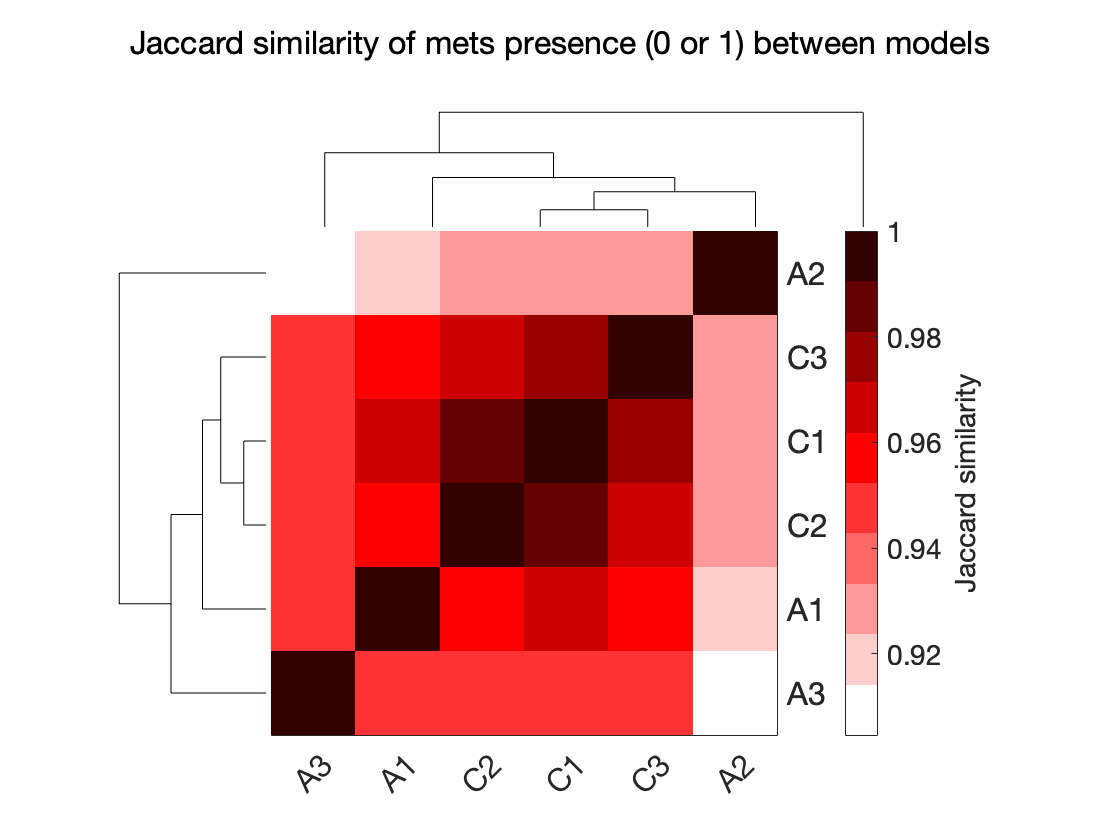

showFigure(plots.struct.jaccardDist.mets)

showFigure(plots.funct.import)
showFigure(plotsOne.funct.import)
showFigure(plots.funct.export)
showFigure(plotsOne.funct.export)

MathWorks::System::IUserException in WebControllerFactory::create(): [Unrecognized method, property, or field 'ViewModel' for class 'handle'.

Error in matlab.ui.internal.componentframework.WebComponentController/getParentView (line 476)
            parentView = parentController.ViewModel;
                         ^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in 

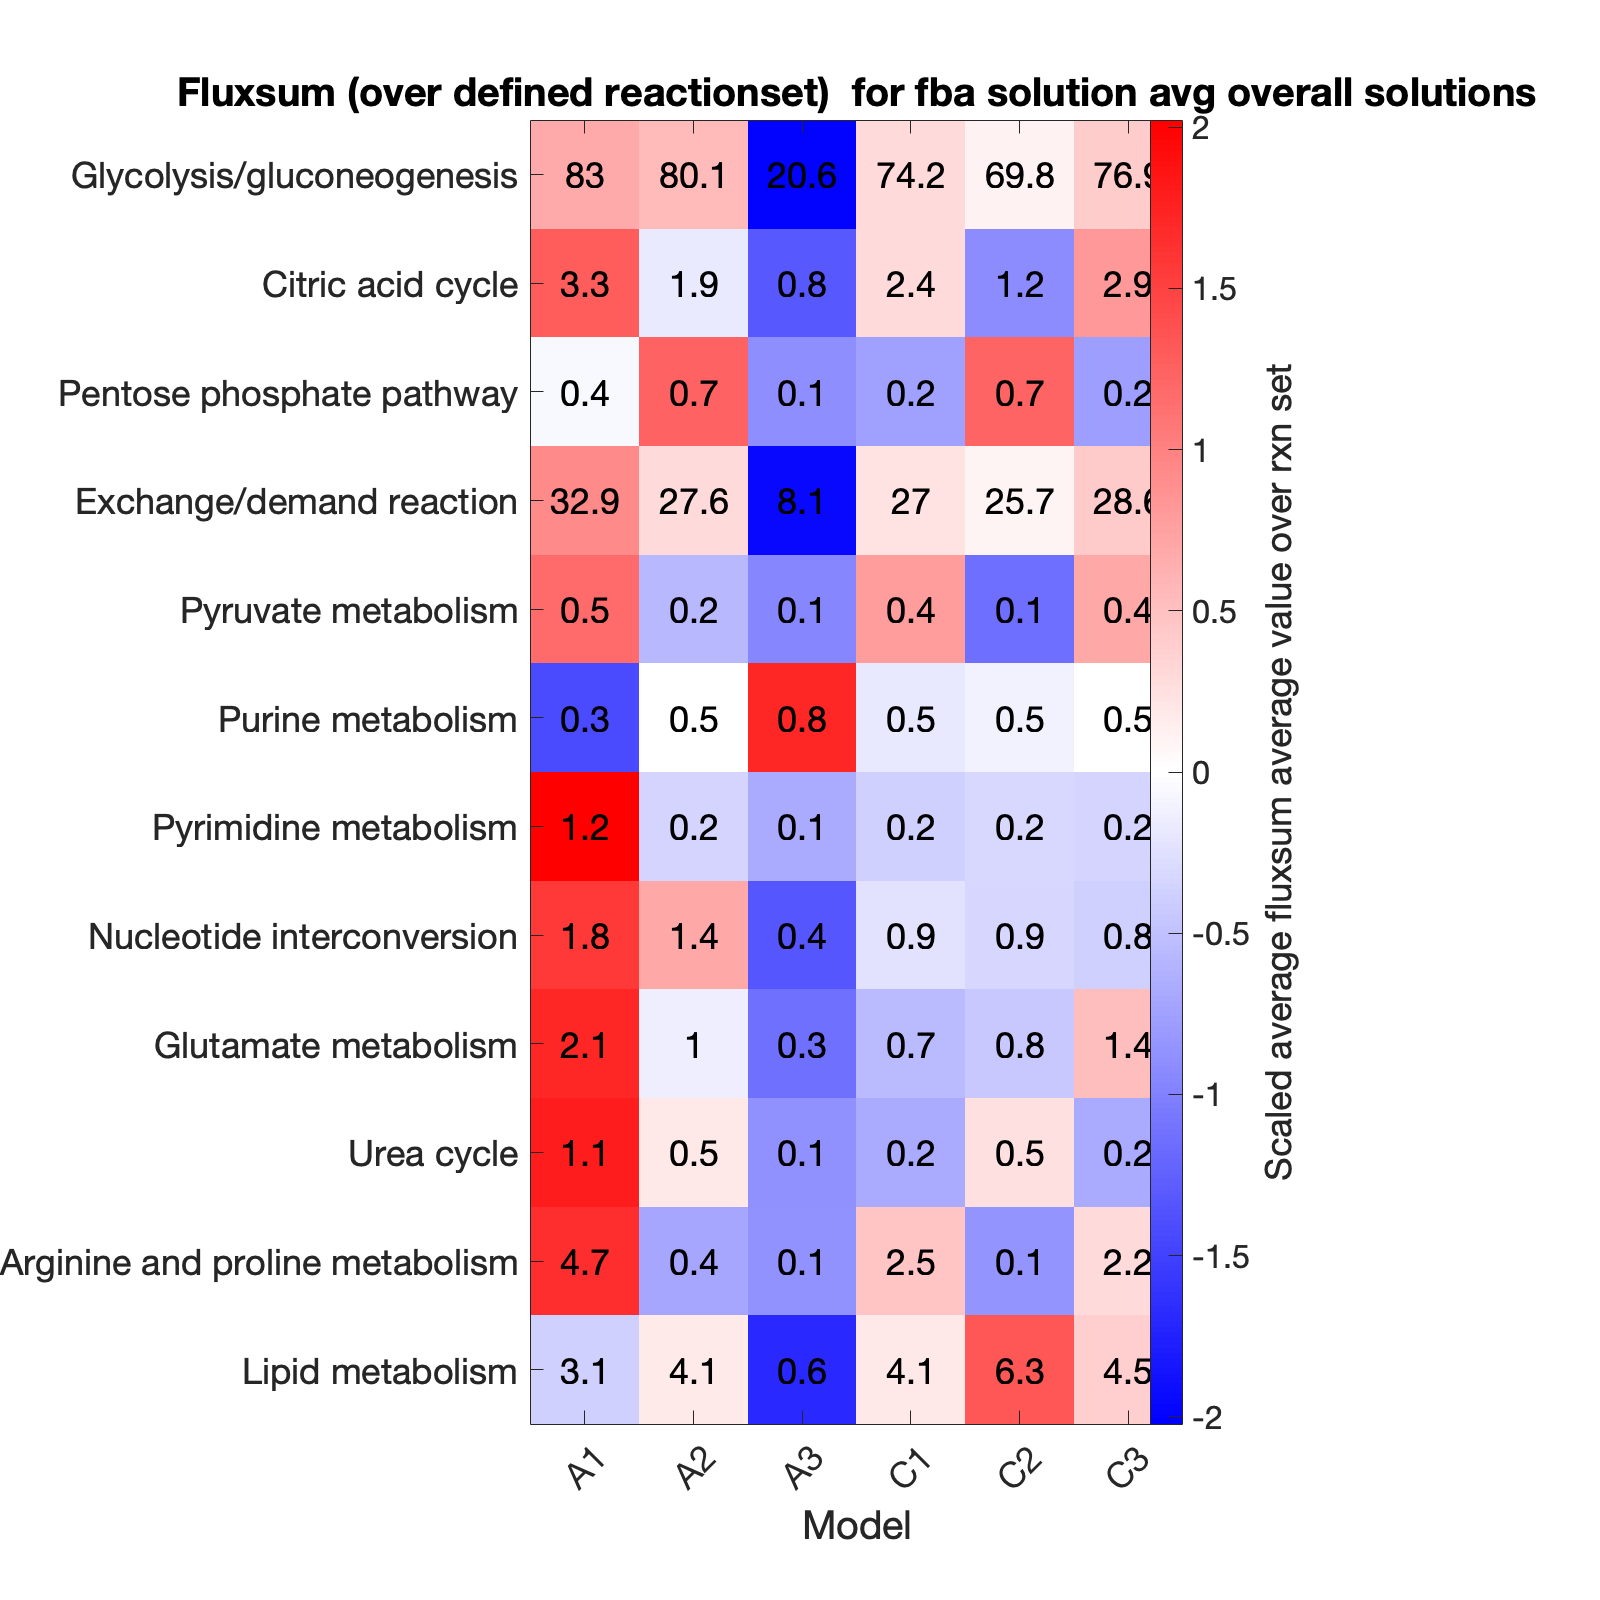

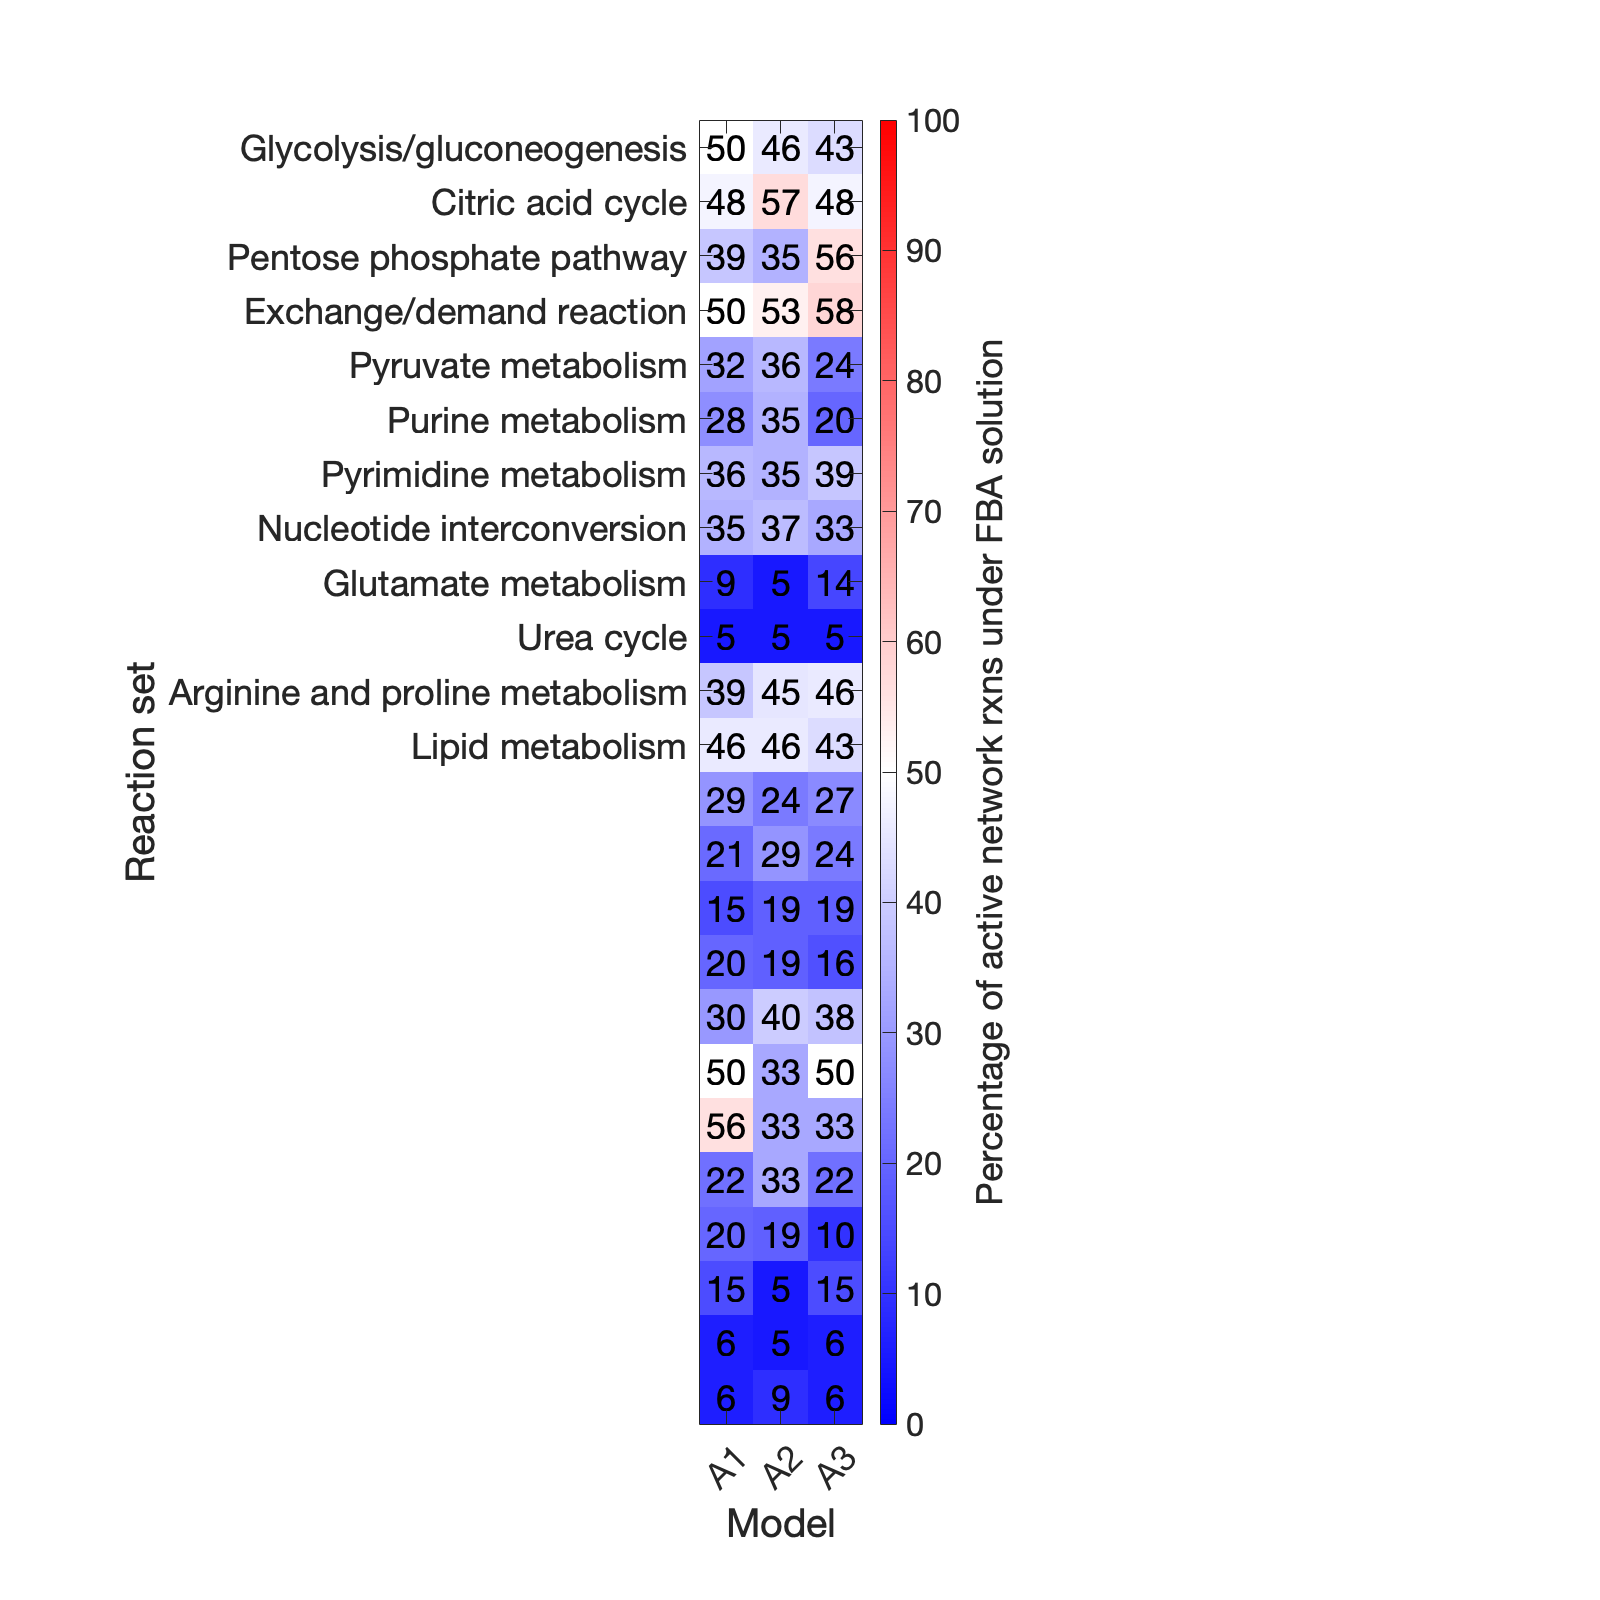

showFigure(plots.funct.fba.heatmapRxnFluxsum);showFigure(plots.funct.fba.heatmapRxnActivityFba)

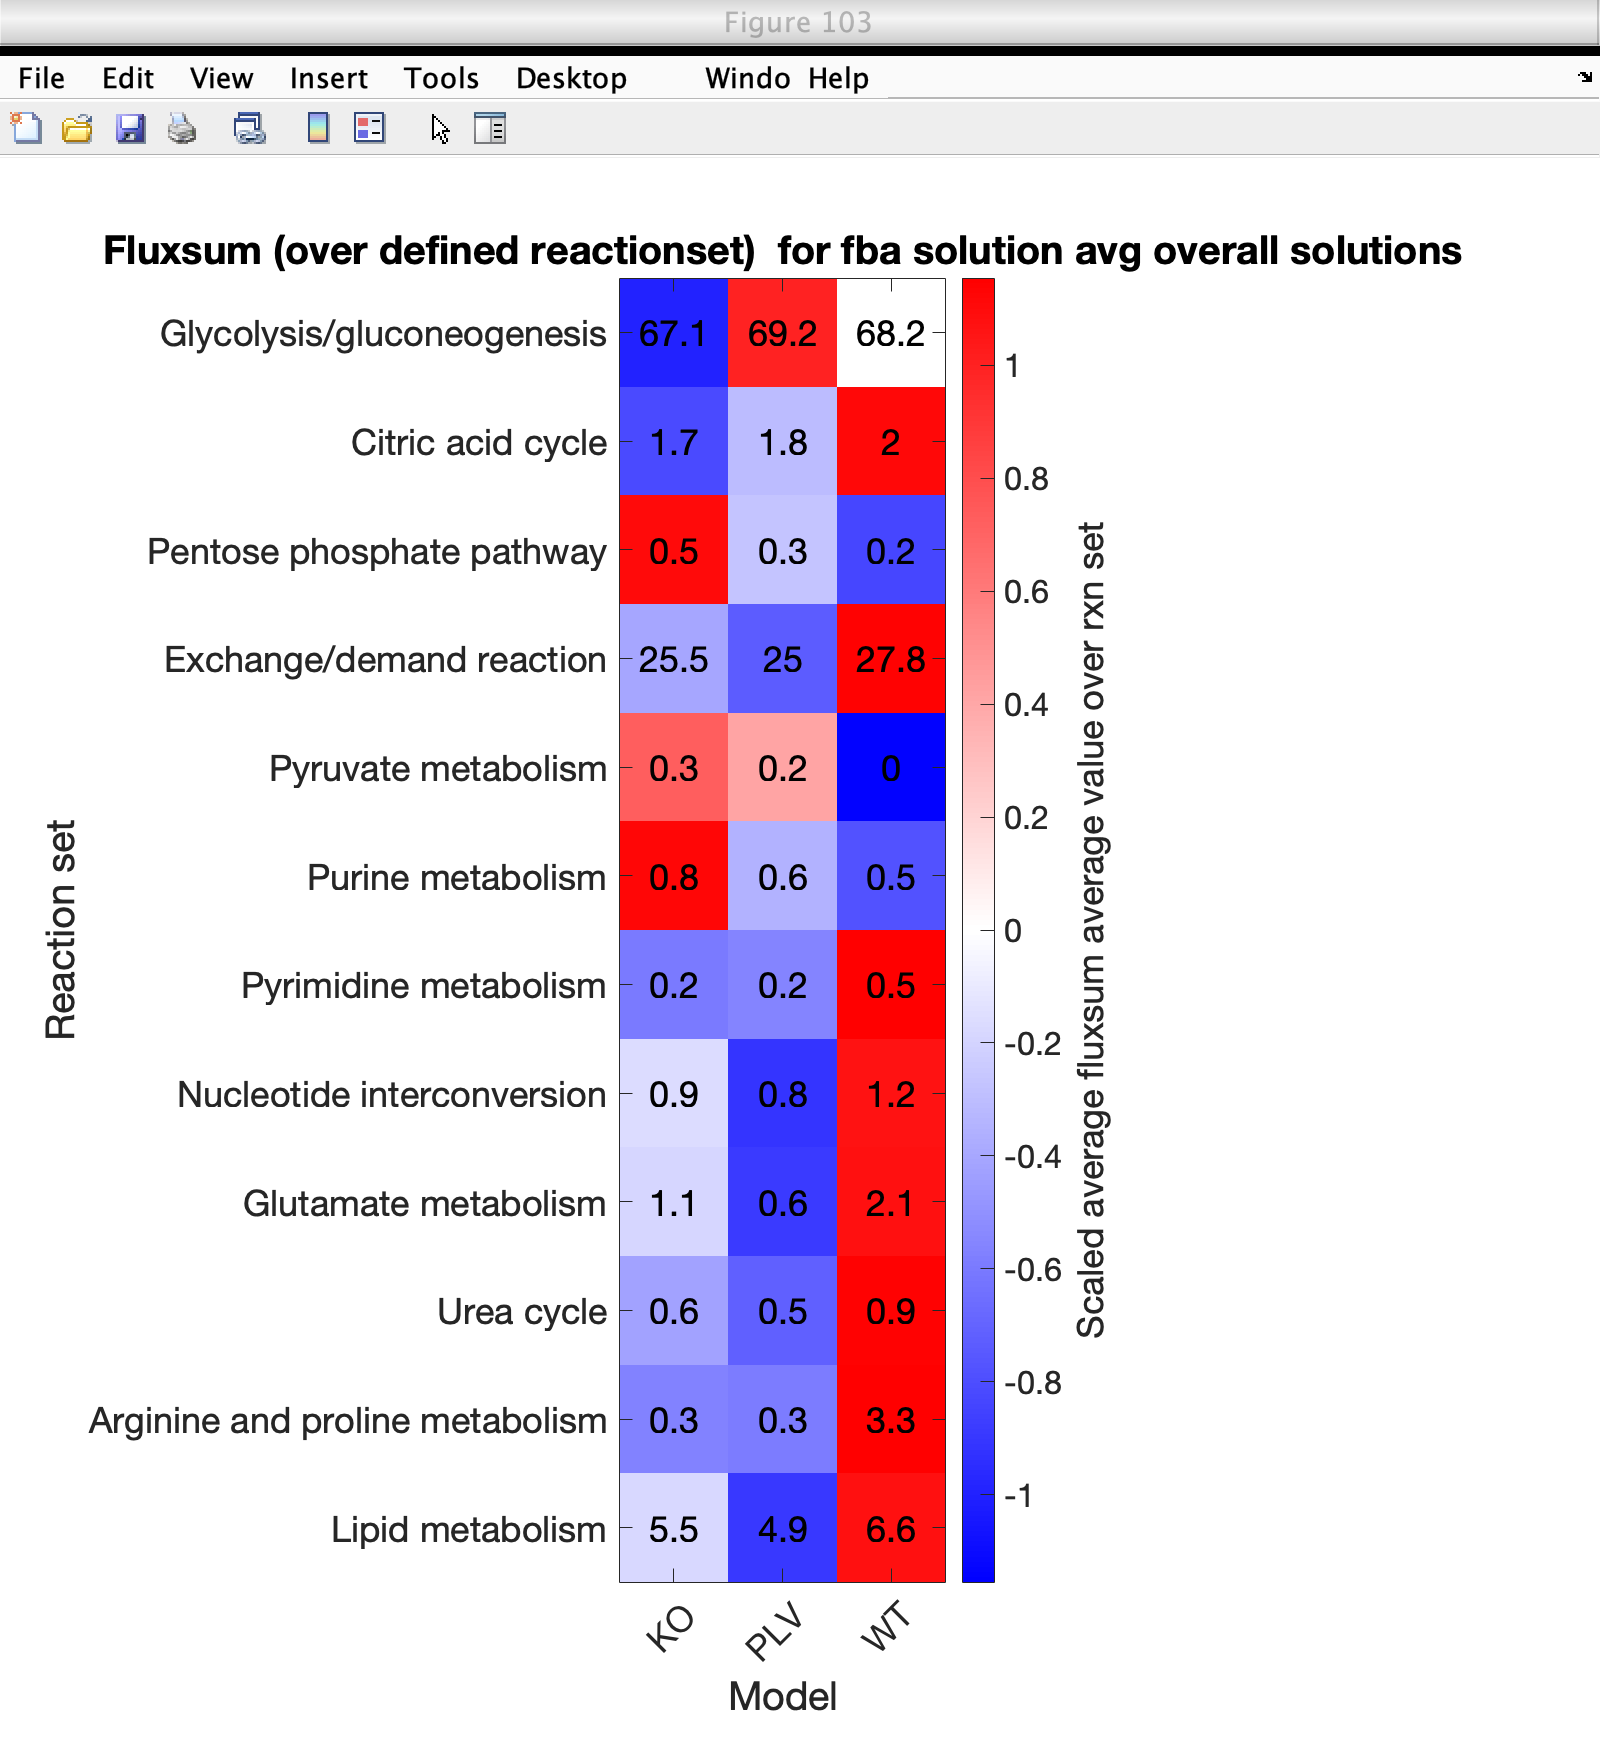

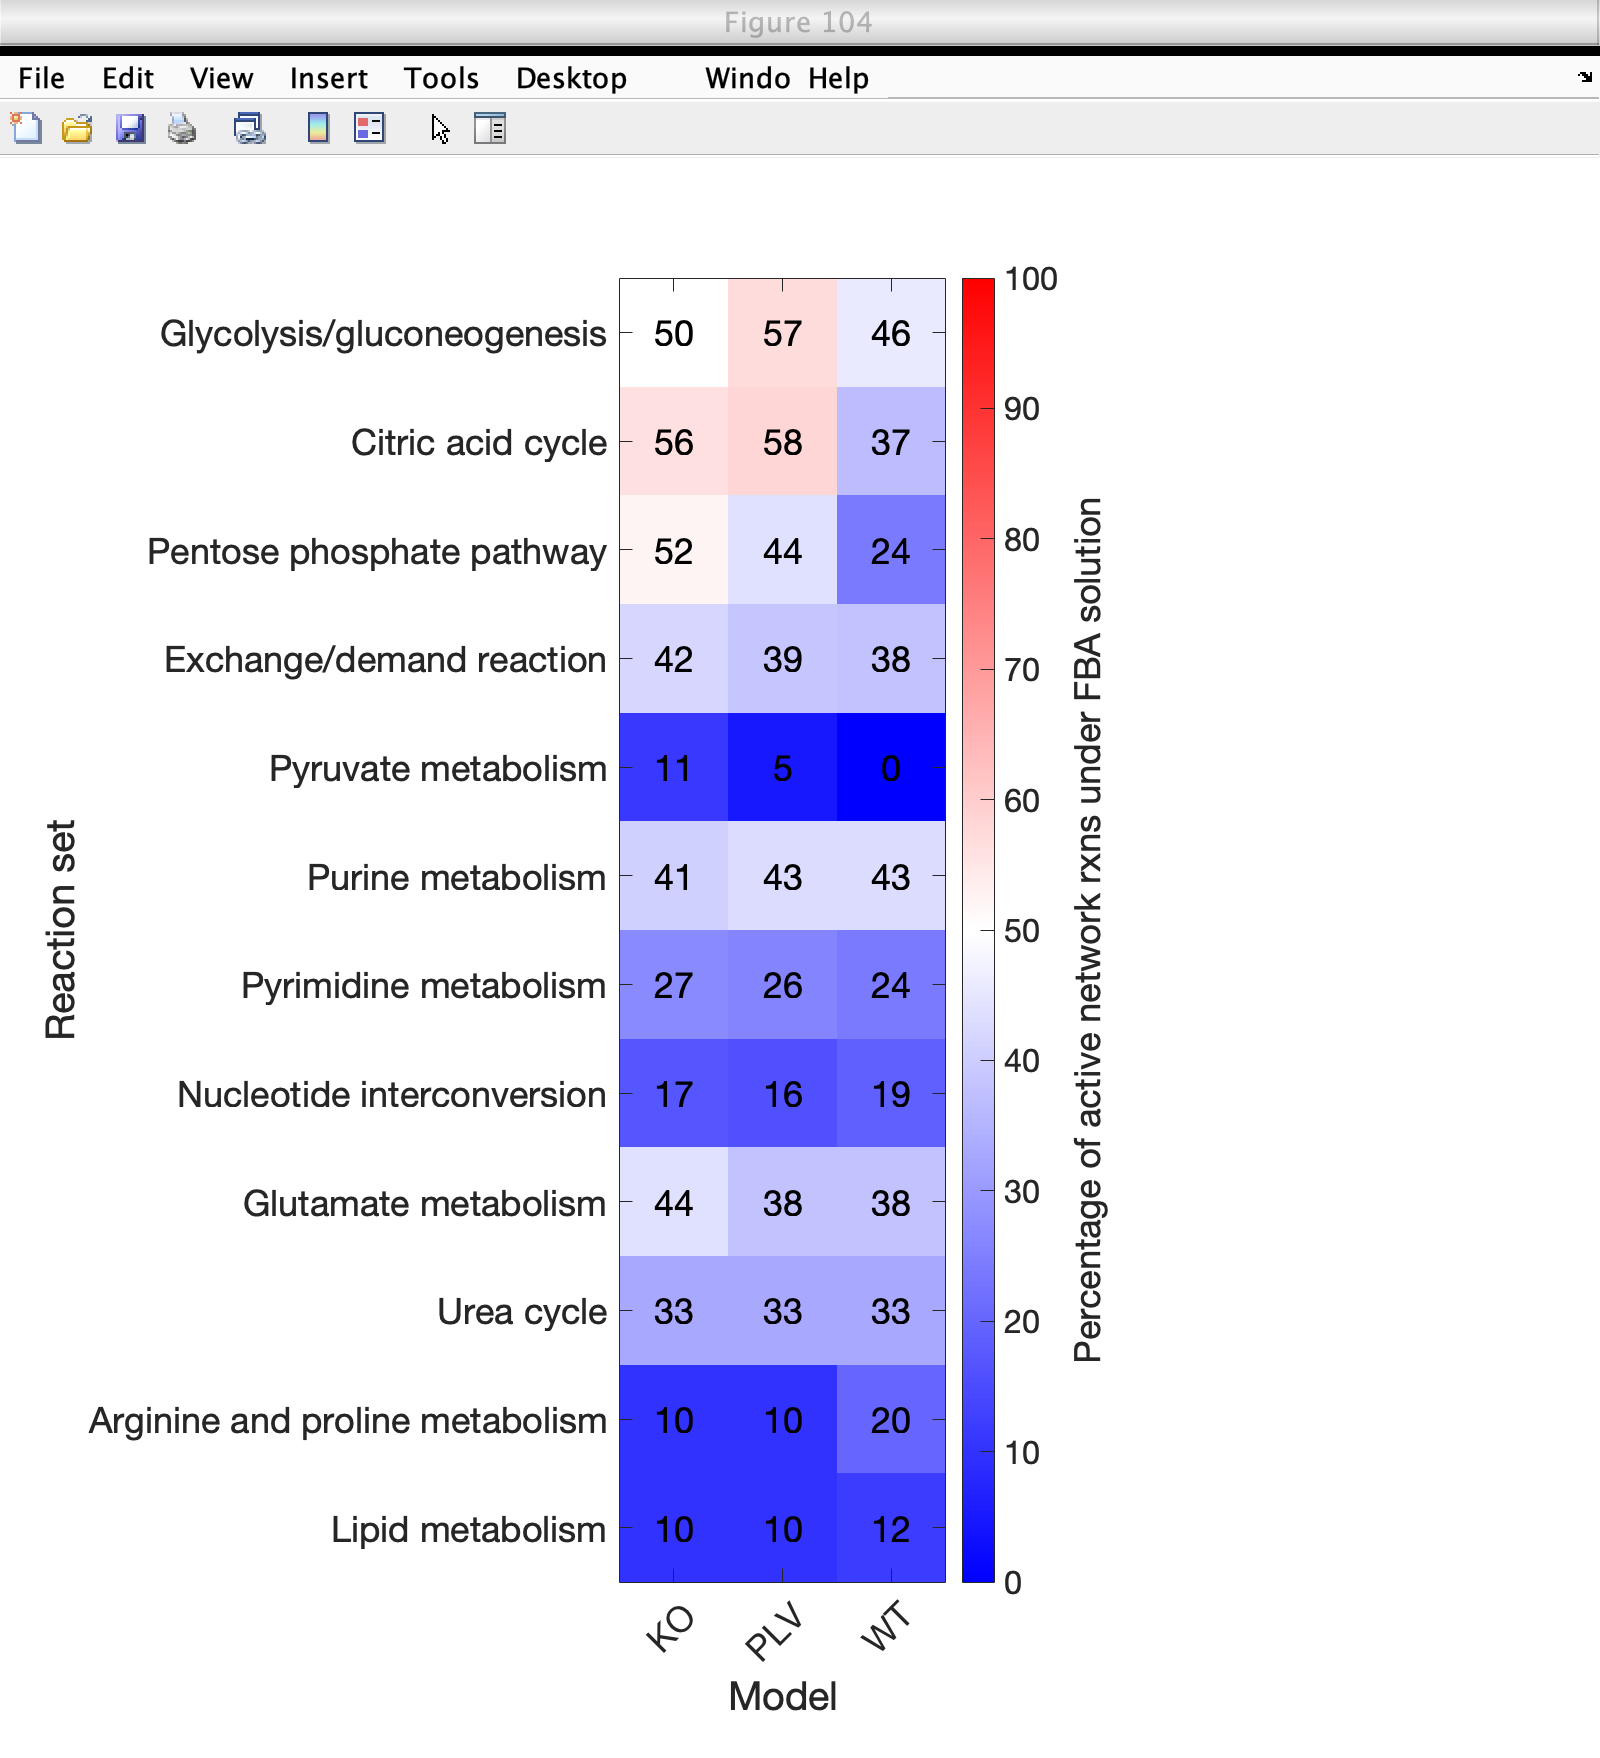

showFigure(plotsOne.funct.fba.heatmapRxnFluxsum);showFigure(plotsOne.funct.fba.heatmapRxnActivityFba)

### Background: 

GSNOR is an enzyme responsible for the denitrosylation of proteins. S-nitrosylation is a reversible post-translational modification of proteins where NO can bind to cystein residue and thereby influence the activity, function and stability of the protein. The S-nitrosylation of proteins is regulated by the production of nitric oxide (NO). Denitroxylation has been found to be downregulated in cancer. We are not sure what causes this downregulation observed in cancer. 

The downreglation of denitrosylation causes a metabolic reprogramming: 

- upregulation of the glycolysis and TCA cycle 

- accumulation of proline & aKG + downregulation of lactate production and succinate 

Here in we have bulk RNAseq data from 3 experimental conditions: 

- WT: the control 

- GSNOR KO -> leading to an increase in nitrosylated proteins and PYCR1 goes up to (expression ? ) 

- GSNOR KO with a re-expression of GSNOR through a plasmid 

### Investigate your results: 

Which of the observations/assumptions made can we reproduce using the metabolic models ? 

### Lactate production 

Lactate production is supposed to go down in the KO condition. Let's check the different layers of our data

FBA & FVA results: 

Lactate production is behaving how expected biologically in the FBA with 'zero', in 'one' the tendencies are the other way around. 

This is probably mainly due to the changes in the glycolysis import. The 'zero' option has less active rxns while the 'one' option has less overall flux through the system. That makes sense. 

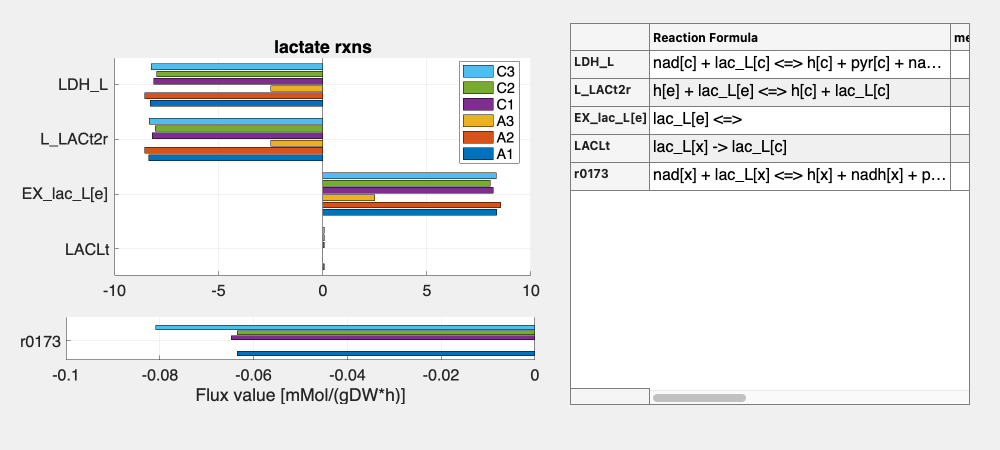

[rxnsMetId,producingMet,matched] = getRxnIDs(sampleProj,referenceModel, "^lac_.*");

getFluxPlot(sampleProj,comparisonName,rxnsMetId, ...
              "thresholdFlux","none","FVA", false ,...
              'titlePlots',"lactate rxns");

The FBA where we optimize for biomass shows us that the KO cells and PLV cells export less lactate. 

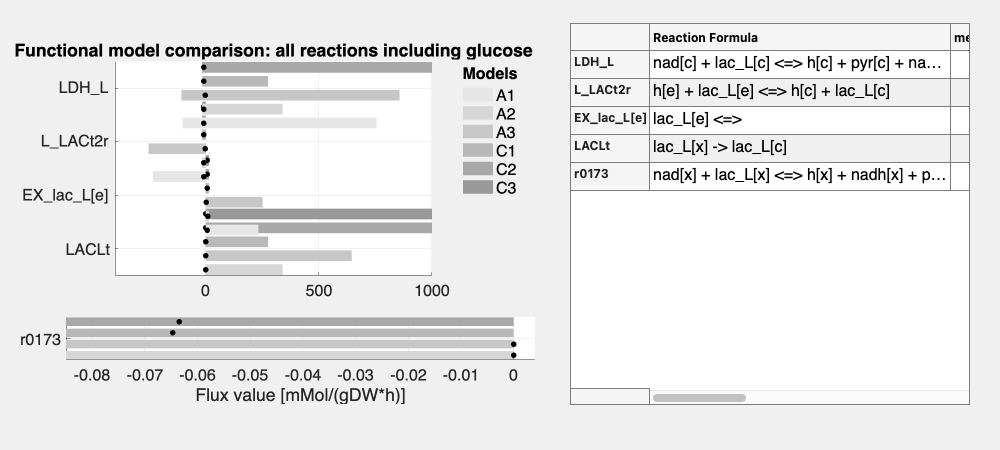

getFluxPlot(sampleProj,comparisonName,rxnsMetId, ...
              "thresholdFlux","none","FVA", true ,...
              'titlePlots',"Functional model comparison: all reactions including glucose");

The FVA results showing us the metabolic flexibility (90% of the biomass) shows that the WT cells have a higher metabolic capacity to export lactate. We also see that the cells can produce pyruvate from lactate according to the FVA results (positive values for LDH_L) - not sure how realistic that is - loop ? 

The loop around lacatae we also see in the sampling results the lactate is converted into pyruvate transported into the peroxisome and then converted back to lactate - thermodynamically infeasible or transport of nadh into peroxisome ? But in total the WT model can export more lactate D and lactate L. 

[rxnsMetId,producingMet,matched] = getRxnIDs(sampleProj,referenceModel, "PDH | OGDH");
getFluxPlot(sampleProj,comparisonName,rxnsMetId, ...
              "thresholdFlux","none","FVA", true ,...
              'titlePlots',"Functional model comparison: all reactions pyruvate metabolism");

For PDHm the WT cells can push to higher  values in comparison to the KO. The same is true for AKGDm (OGDH). 

[rxnsMetId,producingMet,matched] = getRxnIDs(sampleProj,referenceModel, "Glycolysis.*");
getFluxPlot(sampleProj,comparisonName,rxnsMetId, ...
              "thresholdFlux","none","FVA", true ,...
              'titlePlots',"Functional model comparison: all reactions Glycolysis");
[fluxsumSets,plot1] = visualizeFlux(sampleProj, comparisonName,[],{rxnsMetId },...
                                                                     ["Glycolysis"],"all");

showFigure(plots.sampling.heatmapMetsFluxsumSamples)


sum(sampleProj.comparisons.(comparisonName).ksResults.ksMatrix(:,1) > 0.99 & sampleProj.comparisons.(comparisonName).ksResults.pvalMatrix(:,1) < 0.01)





[rxnsMetId,producingMet,matched] = getRxnIDs(sampleProj,referenceModel, "g3p[c.*");
[fluxsumSets,plot1] = visualizeFlux(sampleProj, comparisonName,[],{rxnsMetId },...
                                                                     ["lactate D metabolism"],"all");
[fluxsumSets,plot1] = visualizeFluxsum(sampleProj, comparisonName,[],{rxnsMetId },...
                                                                     ["lactate D metabolism"],"violin");

[rxnsMetId,producingMet,matched] = getRxnIDs(sampleProj,referenceModel, "lac_.* & ^pyr.*");
[fluxsumSets,plot1] = visualizeFlux(sampleProj, comparisonName,[],{rxnsMetId },...
                                                                     ["lactate pyruvate rxns "],"all");

The sampling results (90% of the optimal biomass) show aligned with the results of the FVA and the FBA that the KO cells have a higher capacity to export lactate. But what the sampling also shows us that even though the KO cells can push to higher values for EX_lac_L the likelyhood to obtain as high values as portrayed in the FVA results (max around 200 - 250) seems to be very unlikely (so unlikely that no samples were obtained for that). But still in contrast to the PLV and WT condition we see a shift for the KO condition to given the metabolic modell have a higher likelyhood of exporting higher amounts of lactate. 


[fluxsumSets,plot1] = visualizeFluxsum(sampleProj,comparisonName,[],{rxnsMetId},...
                                                                     ["lactate metabolism"],...
                                                                     "violin",false,false,"orderedSamples", "reactions");
 

### decrease in glycolysis activity 

[rxnsMetId,producingMet,matched] = getRxnIDs(sampleProj,referenceModel, "Glycolysis");

getFluxPlot(sampleProj,comparisonName,rxnsMetId, ...
              "thresholdFlux","none","FVA", false ,...
              'titlePlots',"lactate rxns");
[fluxsumSets,plot1] = visualizeFlux(sampleProj, comparisonName,[],{rxnsMetId },...
                                                                     ["lactate pyruvate rxns "],"all");
[fluxsumSets,plot1] = visualizeFluxsum(sampleProj, comparisonName,[],{rxnsMetId },...
                                                                     ["lactate pyruvate rxns "],"violin");
[fluxsumSets,plot1] = visualizeFluxsum(sampleProj, comparisonName,[],{rxnsMetId },...
                                                                     ["Glycolysis"],"heatmapSampleAllFeatures",false,true,"orderedSamples","incoming");

[rxnsMetId,producingMet,matched] = getRxnIDs(sampleProj,referenceModel, "^NOS2$ | Urea.*");
[fluxsumSets,plot1] = visualizeFlux(sampleProj, comparisonName,[],{rxnsMetId },...
                                                                     ["nitric oxide rxns + urea cycle"],"all");

[rxnsMetId,producingMet,matched] = getRxnIDs(sampleProj,referenceModel, "Pentose phosphate pathway");

[fluxsumSets,plot1] = visualizeFlux(sampleProj, comparisonName,[],{rxnsMetId },...
                                                                     ["Pentose phosphate pathway"],"all");
[fluxsumSets,plot1] = visualizeFluxsum(sampleProj, comparisonName,[],{rxnsMetId },...
                                                                     ["Pentose phosphate pathway"],"violin",false,false,"orderedSamples","incoming");


[rxnsMetId,producingMet,matched] = getRxnIDs(sampleProj,referenceModel, "pro_L.*");
[fluxsumSets,plot1] = visualizeFlux(sampleProj, comparisonName,[],{rxnsMetId },...
                                                                     ["proline rxns "],"all");

[rxnsMetId,producingMet,matched] = getRxnIDs(sampleProj,referenceModel, "OGDH.*");
[fluxsumSets,plot1] = visualizeFlux(sampleProj, comparisonName,[],{rxnsMetId },...
                                                                     ["OGDH rxns "],"all");

rxnsMet = {'LDH_Lm';'LDH_L';'PDHm';'AKGDm'; 'P5CR'; 'EX_progly[e]'; 'EX_4hpro[e]';'EX_pyr[e]'; 'EX_glu_L[e]'; 'EX_lac_D[e]'; 'EX_lac_L[e]';'EX_pro_L[e]'};
[~,rxnsMetId] = ismember(rxnsMet, sampleProj.models.(referenceModel).model.rxns);

[fluxsumSets,plot1] = visualizeFlux(sampleProj, comparisonName,[],{rxnsMetId},...
                                                                     ["GSNOR alterations metabolism"],"all");

#### Size of the context specific models/Feature presence and their inter and outersection between models:

The first step after building a model is to inspect how different the models are, are the meaningful differences between the models that were constructed. Even though that seems trivial when inspecting models build on data from different tissues or different organisms, it is less trivial when the transcrtiptomics data the models are build on are not that heterogeneous, like for in-vitro exeperiments where the only difference is one gene knockdown for example. 

Therefore talking a look at how different the models are in terms of inter and outersections can be critical. 

For the inter- and outersection plots we expect the models to show a high number of intersecting features (genes/reactions/metabolites) since the core metabolism is active in all of the models in order to fullfil the requirement for the biomass. 

- **reaction presence** between models: we see an overlap between all the conditions of over 2000 reactions, which means that 90 % of the reactions are shared between the models, therefore all the functional differences we see in the following analysis come down to the structural differences of those 10% 

- **mets presence** between models: Do the differences between the models on a structural rxns level affect which metabolites can be generated ? Since differen reactions can lead to the production of the same metabolites we expect the outersections to be smaller for the venn diagramm of the metabolites. 

- **gene presence** between models: How many genes are used by the reactions of the outer and intersections ? Most of the genes are involved in multiple rxns + reactions are not all linked to genes, so how many of the reaction changes can actually be mapped to the transcrtiptomics level

**Interpretation:** Given that we here have models with only one knockout we do not expect huge differences + we do expect that a large aspect of the metabolism is the same since the core metabolism needs to be functional. But we have differences at the structural level that can be mapped to genes so to the transcriptomic level. So in the follow up analysis figures, we will investigate where those changes are located in the metabolic network in terms of pathways.

showFigure(plots.struct.intersections.rxns);showFigure(plots.struct.intersections.mets);showFigure(plots.struct.intersections.genes);

**Reaction presence quantified in jaccard similarity: **As implied by the absolute number of reactions in the outer and intersections we can see that a large proportion of the reactions are in all the models, wht a jaccard similarity that is always over 90. We see that the similarity is lowest when comparing the WT with the PLV condition, for metabolites, reactions and genes. We can also see that the jaccard similarity is lowest when computing it over the reaction presence, compared to the genes and metabolites, this also makes sense since not all the reactions are associated with genes and multiple reactions can produce the same metabolites.

showFigure(plots.struct.jaccardDist.rxns);showFigure(plots.struct.jaccardDist.genes);showFigure(plots.struct.jaccardDist.mets);

**Wants to visualize the intersection for a specific set of rxns ? **

pathwayToVis = "Glycolysis/gluconeogenesis";
[glyRxnIdx,producingMet,matched] = getRxnIDs(sampleProj,referenceModel,pathwayToVis );

subsystemFeaturePresence = sampleProj.comparisons.(comparisonName).rxn_mapping_table{glyRxnIdx,:} ~= 0;

% generate venn
[fig,idx, ~] = plotFlexibleVenn(subsystemFeaturePresence,...
                 sampleProj.comparisons.(comparisonName).modelNames, ... 
                 "Structural model comparison: rxns presence in " + pathwayToVis);
% inspecting the reactions that are in the inter and outersections? 
sampleProj.models.(referenceModel).model.rxnNames(idx.WT)
sampleProj.models.(referenceModel).model.rxnNames(idx.KO_WT)


**Want the jaccard similarity over a specific subsystem ?  **A subsystem that makes sense to check is the export and import. Since we gave the cells the same medium to grow on we do not want the exprot and import to be hugely different.

pathwayToVis = "Exchange/demand reaction";
[glyRxnIdx,producingMet,matched] = getRxnIDs(sampleProj,referenceModel, pathwayToVis);
subsystemFeaturePresence = sampleProj.comparisons.(comparisonName).rxn_mapping_table{glyRxnIdx,:} ~= 0;

plotJaccard(subsystemFeaturePresence,...
                 sampleProj.comparisons.(comparisonName).modelNames, ... 
                 "Structural model comparison: rxns presence in " + pathwayToVis);

**All the structural differences that we see in the model comparison how many of them are due to the core reactions defined based on the expression ? **

In the figure below we see that from all the approx. 2500 rxns per  model around 60 percent are in the model because there were binarized to be core model reactions based on the expression of the genes coding for the enzymes of this reaction. So the 60 percent that you see in the upper left figure are the core reactions that made it into the model, but how many core reactions were defined based on the expression data ? Ideally you would want all the core reactions to make it into the model, this means the upper right figure would show us 100 percent. As you see for the models we are currently building the percentage is more around 74%. Adjusting the thresholding of the discretization approach could help to find a trade of between the two figures, as much core reactions as possible in the model, while sustaining to have the higher proportion of core against non-core reactions.

set(plots.struct.coreReactions,'Position', [100 100 700 900]) % resize so it is comfortable to read the whole figure!
showFigure(plots.struct.coreReactions);

Here we see that the outersections for the core reactions is a lot lower compared to the outersections we saw on all the reactions. The core reactions define which of the non-core reactions need to be added to make a model consistent + able to carry biomass. Which pathways do the rxns in the outersections belong too ? 

showFigure(plots.struct.coreReactionsIntersections)

As also seen before for all the reactions the highest amount of rxns (besides the intersection of all models) is associated with the WT (wild type) model. The rxns in the core of model WT specifically are part of mainly Transport and Exchange/demand reactions reactions, but also Fatty acid oxidation and Bile acid synthesis. In addition the KO model shares a few reactions of the Fatty acid oxidation with the WT and the PLV model (2nd and 5th bar). This plot serves more as a QC to check that the rxns that are added to the core and are thereby defining the model construction are not only Exchangers and Transport rxns but also other parts of the metabolism. Interestingly we see that the absence of some of some core rxns of the Fatty acid oxidation seems to play a major role in the differences between the models. 

**QC - overview of the discretization of the data:**

As mentioned previously the core reactions are defined on basis of a discretization step. Here we get an overview about how the genes that are in the model were discretized. 

The first figure (left) shows the discretization of the transcrtiptomics data on basis of the approx. 1200 genes that are defined in the metabolic model. Around 50 % percent were after the application of a sample specifc thershold been categorized to be active (1), around 3 percent were categorized to have an unknown expression status (0) and 10-20 % are discretized to be unexpressed (-1). So we see that only 50 percent of the genes that are in our  context specific models are also labeled to be active, this is due to the fact that one reaction is connected to multiple genes and therefore a gene can still be in the gpr rules of the model while not being discretized as active. This we then see when we switcht from the gene level to the reaction level (middel subfigure) where the mapping of the gene expression status to the rxn activation status is made, and here we see the model is compromised of 60 percent of reactions for which the discretization status is (1)( this is the core we saw in the previous figure already) while around 40 percent are through to have a unknown status. As you can see the reactions with 0 status can be added to the mdoel while the reactions with -1 will not be added to the model (with only a few exceptions - hence the blue bar on the bottom of the 2 rightmost subfigures). After looking at the discretization status per sample the samples are combined into the respective models, and as we see in the rightmost plot there is no big changes in the discretization status after applying the consensus proportion. The consensus proportion is something that can be adjusted too. With this figures it is important to check that we see the same tendendies in discretization on the sample as on the conrresponding model level. Which we do see here - no outliers on the sample level that could influence the consensus model construction.

set(plots.struct.dataDiscretization,'Position', [100 100 3000 2000]) % resize so it is comfortable to read the whole figure!
showFigure(plots.struct.dataDiscretization)


**Which subsystem is enriched for structural changes? **

This figure shows in which subsystem the structural changes can be found. The heatmap is ordered by the variance in rxn count between models. So at the top you will find pathways which in absolute rxns counts are most different between models. The number of rxns per pathway is written into the tiles, while the color indicates how many of the rxns from the reference model can be found in each of the context specific models. 

A few observations can be made on basis of this figure and will be discussed in the following: 

- The heparan sulfate degradation is the subsystem which has the most difference in rxn count. This means that for the WT all the rxns that are in the reference model are retained, while for the KO and PLV model the reactions are eradicated. Of note here is that looking at the core reactions that are specific to WT, there is no reaction from the heparan subsystem, stating the question why we have so much structural change in this subsystem even though there is nothing in the core ? Maybe a metabolite produced by another subsystem is produced in WT and not in the KO & PLV. So it does not have to be metabolized in the PLV & KO model ?? A similar behaviour can be observed for the Chondroitin synthesis

- Fatty acid oxidation is a big subsystem and for all of the models around 50 % of the reactions from the reference model are kept. But there are more reactions in the WT model, which makes sense since we saw that 15 of the reactions defined to be core in WT but not in the other two models are form the Fatty acid oxidation. 

- The Biotin metabolism is specifically not active in the PLV model, while for the WT model we have seen that there are 2 rxns which are specific for the WT model only this does not explain why the biotin metabolism is active in KO but not in PLV. 

Paper linking the degradation of heparan sulfate to NO. The KO of GSNOR leads to less bioavailable NO and therefore the heparan sulfate degradation does not take place ? see publication: [https://www.sciencedirect.com/science/article/pii/S0021925819717980?via%3Dihub#bib23](https://www.sciencedirect.com/science/article/pii/S0021925819717980?via%3Dihub#bib23)

heparan sulfate as mudlator of breast cancer progression ? https://pmc.ncbi.nlm.nih.gov/articles/PMC3747466/?utm_source

set(plots.struct.reactionPathwayPresence,'Position', [100 100 500 500]) % resize so it is comfortable to read the whole figure!
showFigure(plots.struct.reactionPathwayPresence)

pathwayToVis = "Chondroitin synthesis";

[glyRxnIdx,producingMet,matched] = getRxnIDs(sampleProj,referenceModel, pathwayToVis);

subsystemFeaturePresence = sampleProj.comparisons.(comparisonName).rxn_mapping_table{glyRxnIdx,:} ~= 0;

% generate venn
[fig,idx, ~] = plotFlexibleVenn(subsystemFeaturePresence,...
                 sampleProj.comparisons.(comparisonName).modelNames, ... 
                 "Structural model comparison: rxns presence in " + pathwayToVis);
sampleProj.models.(referenceModel).model.rxnNames(idx.KO_WT)
sampleProj.models.(referenceModel).model.rxns(idx.WT)


### Functional analysis of the models: FBA, FVA and sampling

[sampleProj,comparisonName] = modelsComparison(sampleProj,modelList, analysisID,...
                                             referenceModel,"modelFunctionalComparison",identifier);

**On what do the models grow ? FBA solution: **

plots = sampleProj.comparisons.(comparisonName).plots;
showFigure(plots.funct.import)
showFigure(plots.funct.export)

showFigure(plots.funct.fba.heatmapRxnActivityFba)
showFigure(plots.funct.fba.heatmapRxnFluxsum)
showFigure(plots.funct.fvaSim.hist)
showFigure(plots.funct.fvaSim.enrich)
set(plots.funct.objValue,'Position', [100 100 500 400]) % resize so it is comfortable to read the whole figure!
showFigure(plots.funct.objValue)
showFigure(plots.funct.fba.heatmapMetsFluxsum)
showFigure(plots.funct.fba.heatmapRxnFluxsum)


showFigure(plots.funct.import)

[sampleProj,comparisonName] = modelsComparison(sampleProj,modelList, analysisID,...
                                            referenceModel,"modelSamplingComparison",identifier);


plots = sampleProj.comparisons.(comparisonName).plots

showFigure(plots.sampling.heatmapMetsFluxsumSamples);
set(plots.sampling.heatmapRxnFluxsum,'Position',[100 100 1000 1000])
showFigure(plots.sampling.heatmapRxnFluxsum);
showFigure(plots.sampling.heatmapRxnFluxsumSamples);

showFigure(plots.sampling.heatmapMetsFluxsum);showFigure(plots.sampling.heatmapMetsFluxsumSamples);




showFigure(plots.funct.fba.heatmapRxnFluxsum); 
showFigure(plots.sampling.violinFluxGlycolysisgluconeogenesis.fig1); showFigure(plots.sampling.violinFluxGlycolysisgluconeogenesis.fig2);showFigure(plots.sampling.violinFluxGlycolysisgluconeogenesis.fig3)
showFigure(plots.sampling.violinFluxsumGlycolysisgluconeogenesis.fig1); showFigure(plots.sampling.violinFluxsumGlycolysisgluconeogenesis.fig2);showFigure(plots.sampling.violinFluxsumGlycolysisgluconeogenesis.fig3)

test for proline metabolism

[rxnsMetId,producingMet,matched] = getRxnIDs(sampleProj,referenceModel, "^succ[.*");

getFluxPlot(sampleProj,comparisonName,rxnsMetId, ...
              "thresholdFlux","none","FVA", false ,...
              'titlePlots',"Functional model comparison: all reactions including proline");

[fluxsumSets,plot1] = visualizeFluxsum(sampleProj,comparisonName,[],{rxnsMetId},...
                                                                     ["succinate metabolism"],...
                                                                     "violin",false,false,"orderedFba", "reactions");
    
    


[fluxsumSets,pl] = visualizeFlux(sampleProj,comparisonName,[],{rxnsMetId},...
                                                                     ["succinate metabolism"],...
                                                                      "all");

showFigure(plots.funct.objValue);
sampleProj.models.KO.analysis.FBA.f
sampleProj.models.PLV.analysis.FBA.f
sampleProj.models.WT.analysis.FBA.f

findEX_Rxns(sampleProj.models.(referenceModel).model, "biomass_reaction")

[rxnsMetId,producingMet,matched] = getRxnIDs(sampleProj,referenceModel, "pro_LT[.* | biomass.*");

getFluxPlot(sampleProj,"A1_vs_A2_vs_A3_vs_C1_vs_C2_vs_C3___test" ,rxnsMetId, ...
              "thresholdFlux","none","FVA", false ,...
              'titlePlots',"Functional model comparison: all reactions including proline & pro  LT");

[fluxsumSets,plot1] = visualizeFlux(sampleProj,"A1_vs_A2_vs_A3_vs_C1_vs_C2_vs_C3___test" ,[],{rxnsMetId},...
                                                                     ["proline metabolism"],"all");

Error using  / 
Matrix dimensions must agree.

Error in Violin (line 124)
                width = 0.3/max(density);

Error in violinplot (line 94)
            violins(n) = Violin(thisData, n, varargin{:});

Error in 


[fluxsumSets,plot1] = visualizeFluxsum(sampleProj,"A1_vs_A2_vs_A3_vs_C1_vs_C2_vs_C3___test" ,[],{rxnsMetId},...
                                                                     ["proline metabolism"],...
                                                                     "violin",false,false,"orderedSamples", "reactions");

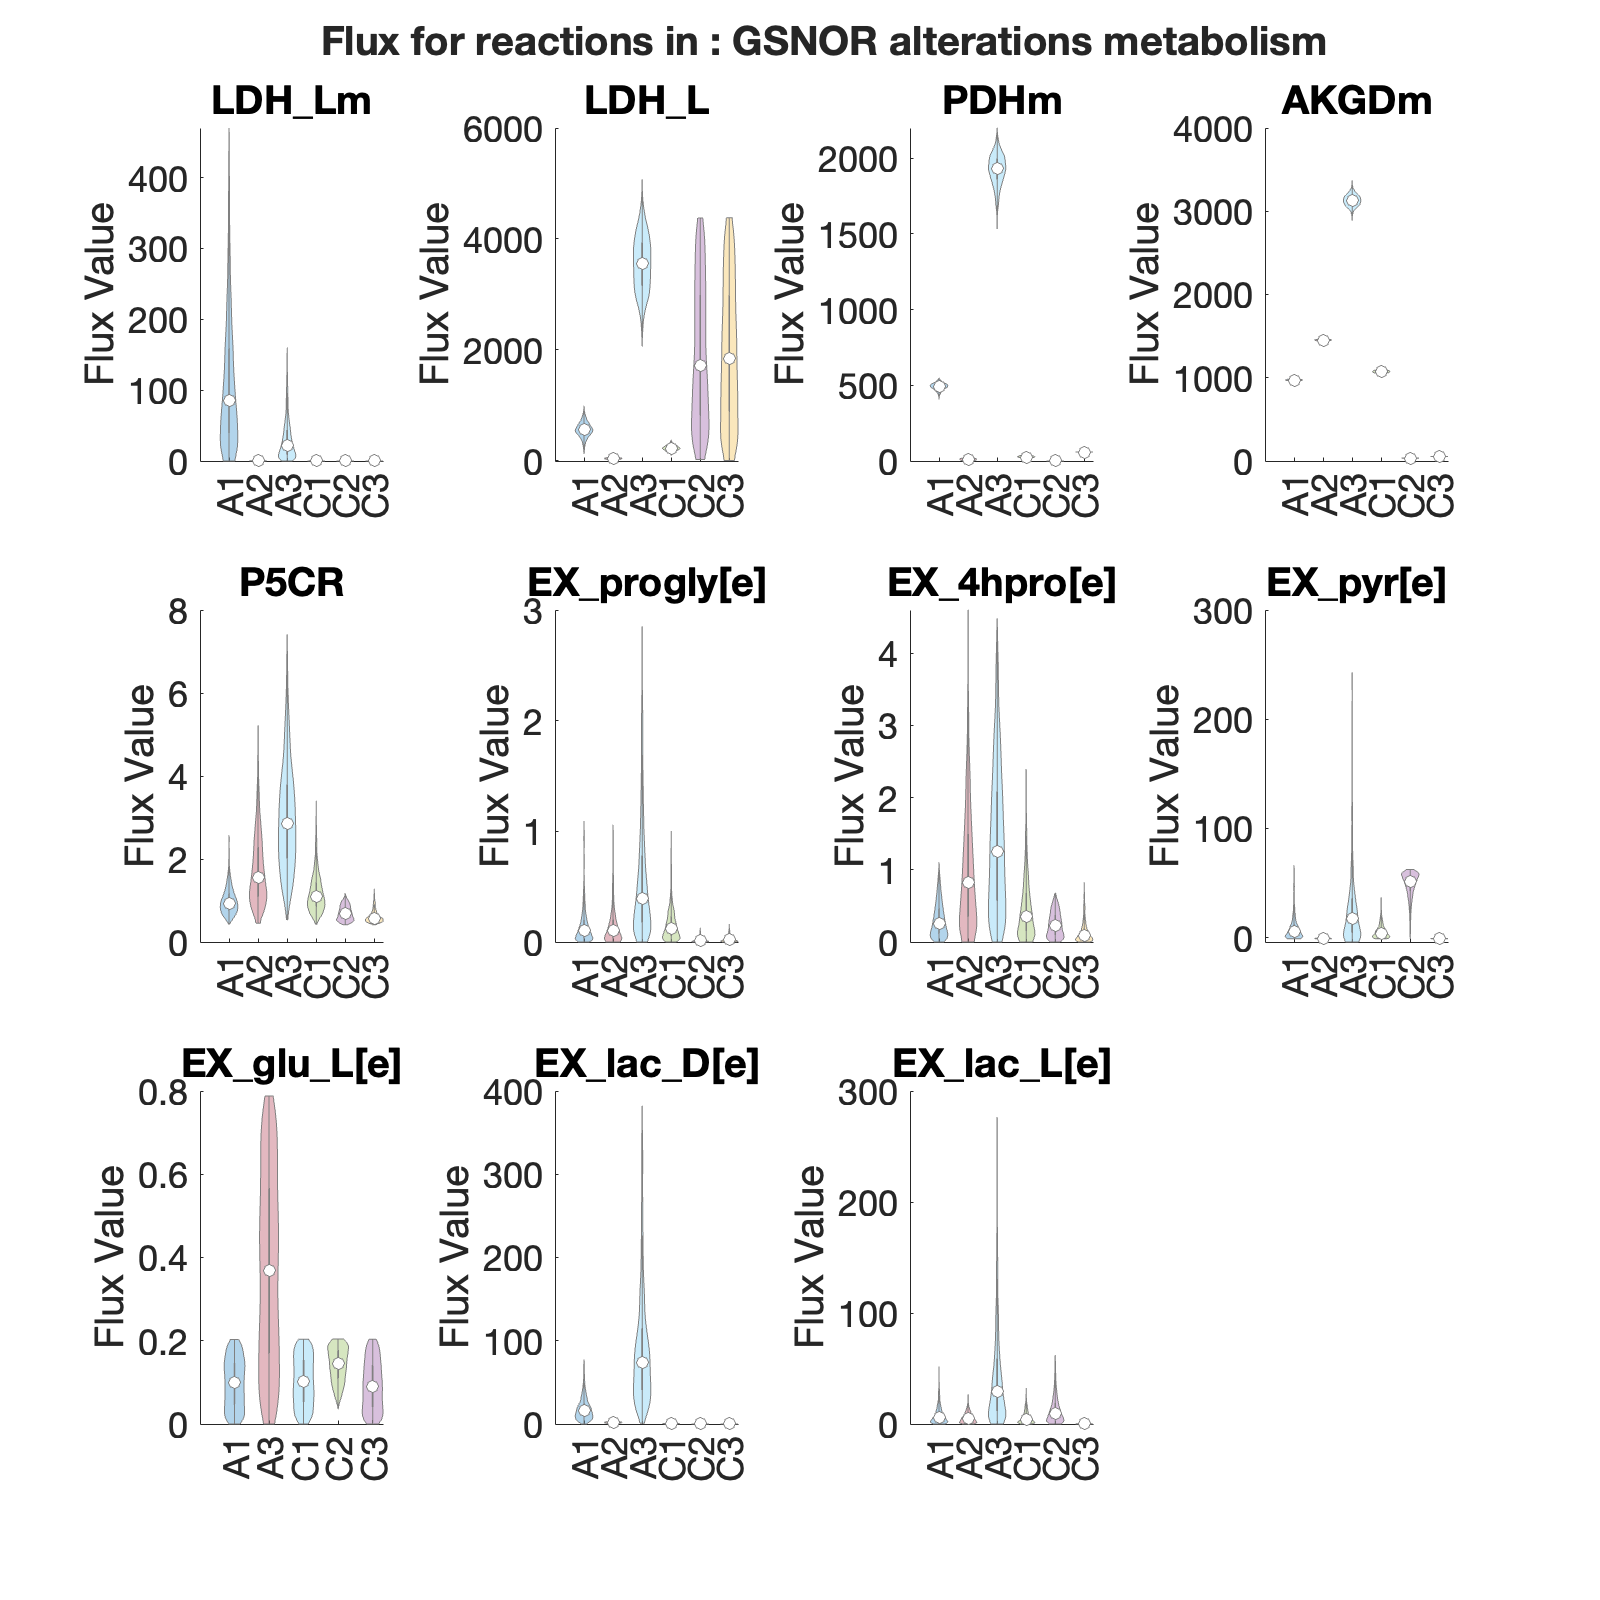

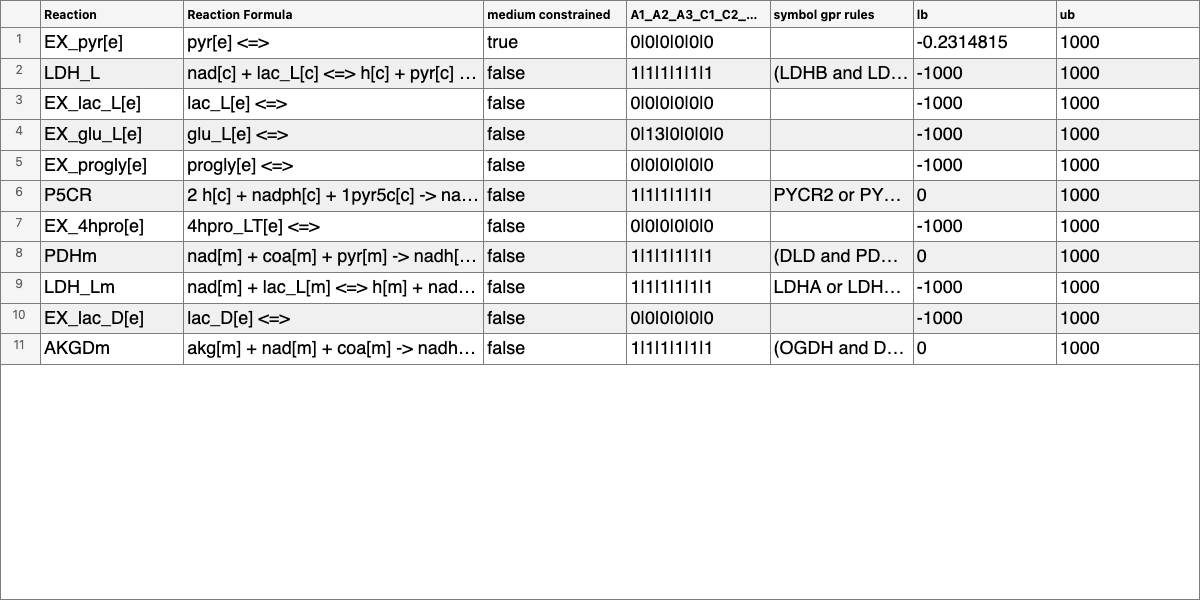

[rxnsMetId,producingMet,metNames] = getRxnIDs(sampleProj,referenceModel, "^lac_D.*");

%rxns_met = findRxnsFromMets(sampleProj.models.(referenceModel).model, met_names);
rxnsMet = {'LDH_Lm';'LDH_L';'PDHm';'AKGDm'; 'P5CR'; 'EX_progly[e]'; 'EX_4hpro[e]';'EX_pyr[e]'; 'EX_glu_L[e]'; 'EX_lac_D[e]'; 'EX_lac_L[e]';'EX_pro_L[e]'};
[~,rxnsMetId] = ismember(rxnsMet, sampleProj.models.(referenceModel).model.rxns);



[fluxsumSets,plot1] = visualizeFlux(sampleProj, comparisonName,[],{rxnsMetId},...
                                                                     ["GSNOR alterations metabolism"],"all");

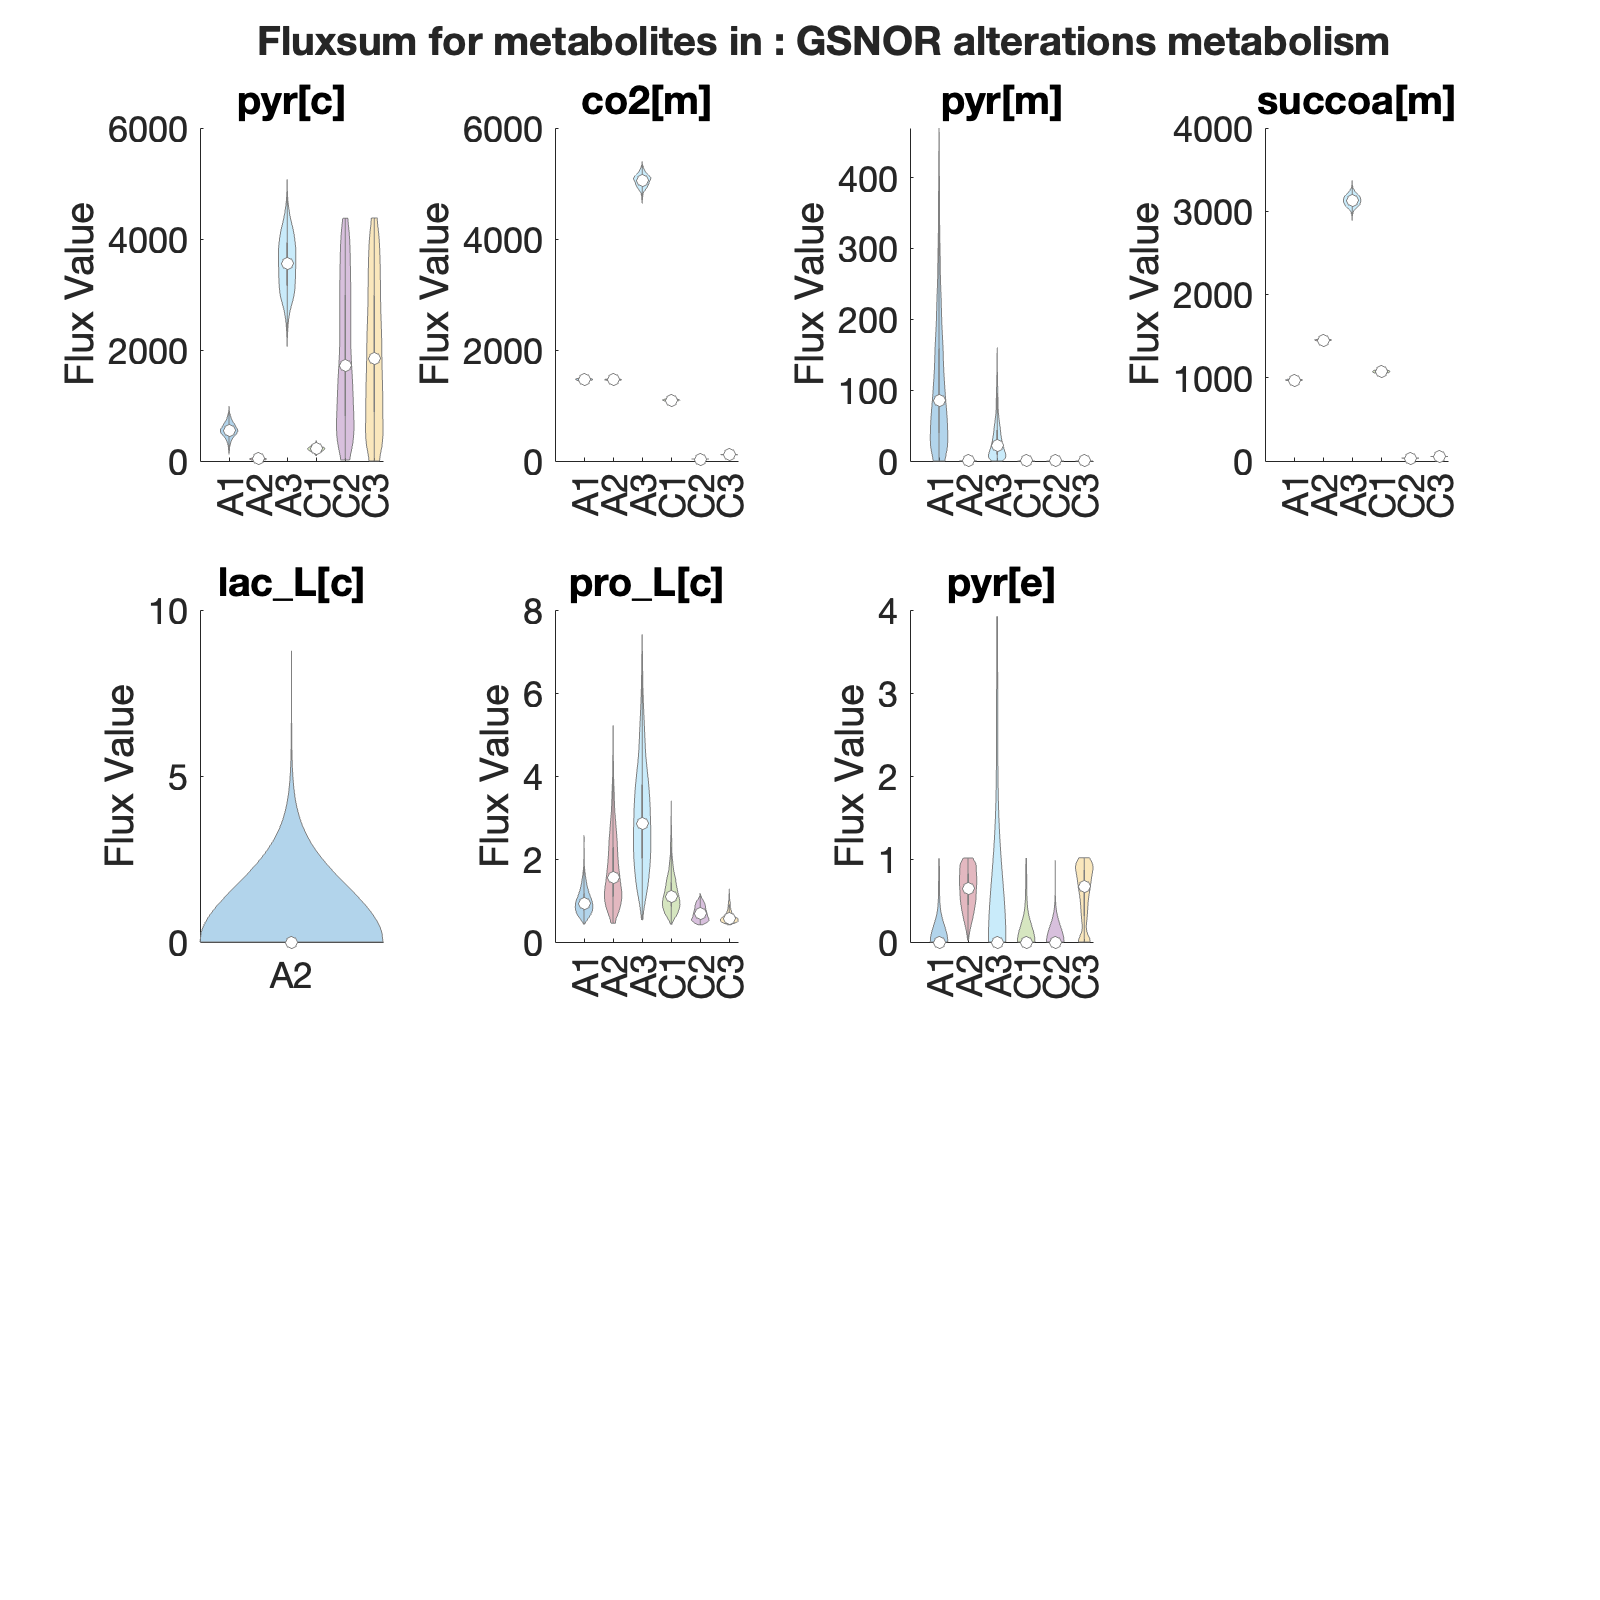

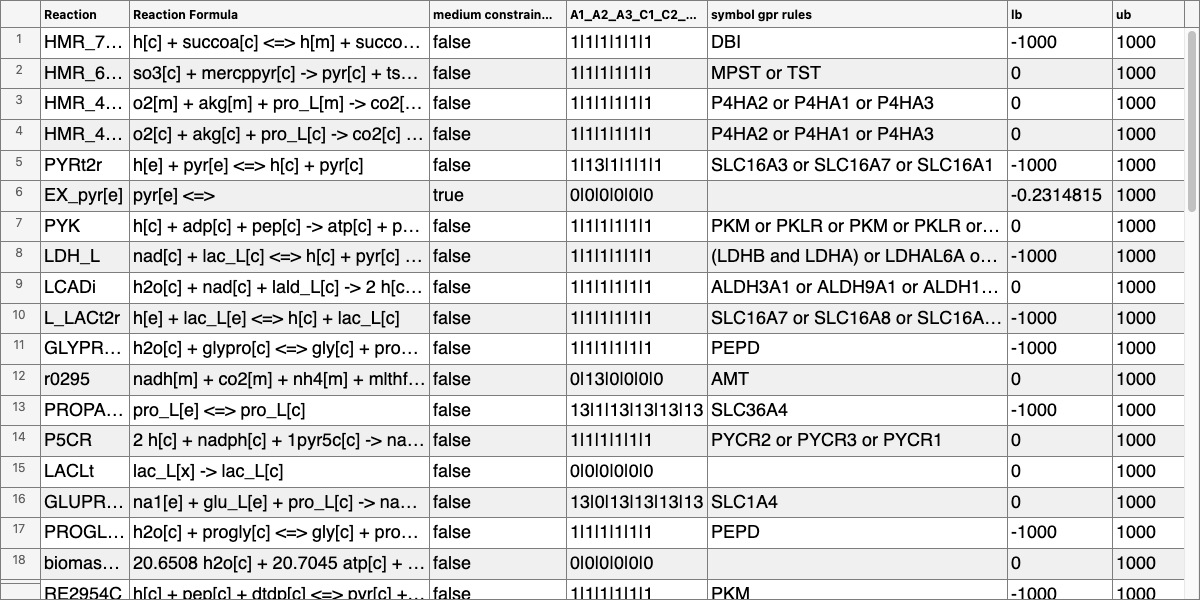

[fluxsumSets,plot1] = visualizeFluxsum(sampleProj,comparisonName,[],{rxnsMetId},...
                                                                     ["GSNOR alterations metabolism"],...
                                                                     "violin",true,false,"orderedSamples", "reactions");

[rxnsMetId,producingMet,metNames] = getRxnIDs(sampleProj,referenceModel, "^glc_D[.*");

getFluxPlot(sampleProj,comparisonName,rxnsMetId, ...
              "thresholdFlux","none","FVA", false ,...
              'titlePlots',"Functional model comparison: all reactions including glucose");
[idx_pathways,names_pathways] = getDefaultSubsystems(sampleProj, referenceModel); 



### Increase of metabolites in the glycolysis: 

- more import of glyc for the KO model - less export of lactate -> where does the rest go ? 

- decreased transport from the glycolysis to the TCA cycle ?  -> decrease in PDHm du to the nitrosylation of that enzyme in KO 

- decrease of transport to lactate -> decrease in activity of LDH -> incrase of lactate export ? -> in KO ?

[rxnsMetId,producingMet,metNames] = getRxnIDs(sampleProj,referenceModel, "^LDH_L | ^PDH | ^EX_glc_ | ^EX_lac_ ");

getFluxPlot(sampleProj,comparisonName,rxnsMetId, ...
              "thresholdFlux","none","FVA", false ,...
              'titlePlots',"Functional model comparison: reactions glycolysis & lactate export");



[fluxsumSets,plot1] = visualizeFlux(sampleProj, comparisonName,[],{rxnsMetId},...
                                                                     ["lactate and glucose metabolism"],"all");


[rxnsMetId,producingMet,metNames] = getRxnIDs(sampleProj,referenceModel, "^glc_D[.*");

getFluxPlot(sampleProj,comparisonName,rxnsMetId, ...
              "thresholdFlux","none","FVA", false ,...
              'titlePlots',"Functional model comparison: glucose");
[fluxsumSets,plot1] = visualizeFlux(sampleProj, comparisonName,[],{rxnsMetId},...
                                                                     ["glucose metabolism"],"all");

[fluxsumSets,plot1] = visualizeFluxsum(sampleProj,comparisonName,[],{rxnsMetId},...
                                                                     ["glucose metabolism"],...
                                                                     "violin",false,false,"orderedSamples", "reactions");


[rxnsMetId,producingMet,metNames] = getRxnIDs(sampleProj,referenceModel, "gluside_hs[.*");

[fluxsumSets,plot1] = visualizeFlux(sampleProj, comparisonName,[],{rxnsMetId},...
                                                                     ["precurser glucose gluside"],"all");

[rxnsMetId,producingMet,metNames] = getRxnIDs(sampleProj,referenceModel, ".*Cis-Aconitate.* | cit[m.*");% | .*HC00342.* | Citric acid cycle");% | GAPDH | LDHA");
[fluxsumSets,plot1] = visualizeFlux(sampleProj, comparisonName,[],{rxnsMetId},...
                                                                     ["Cis-Aconitate paper reactions"],"all");